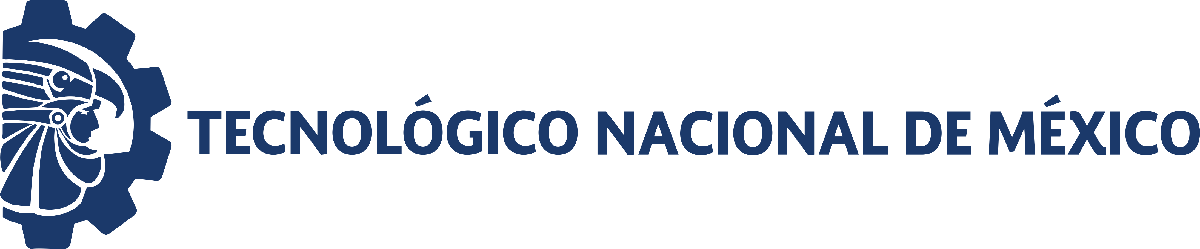                                 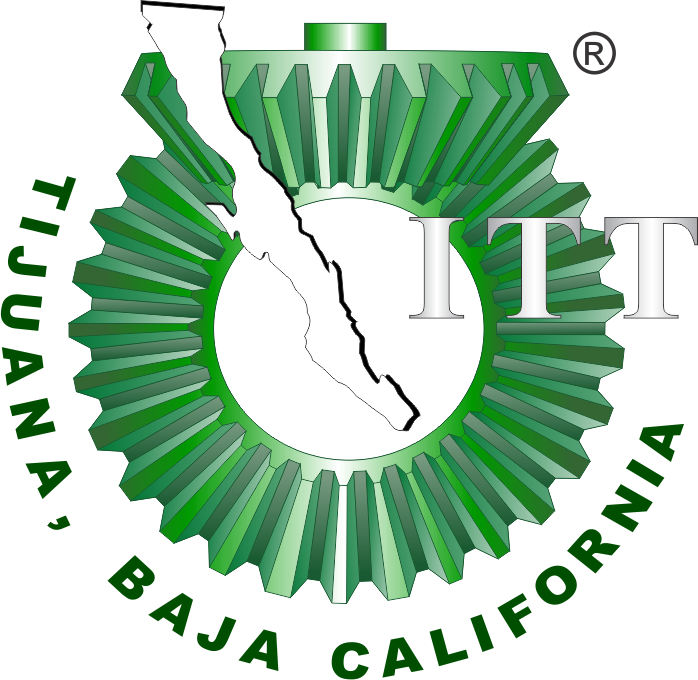

# Práctica 3: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[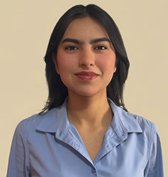]

Nombre del alumno: Valeria Camacho Lopez

Número de control: C22211475

Correo institucional: l22211475**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

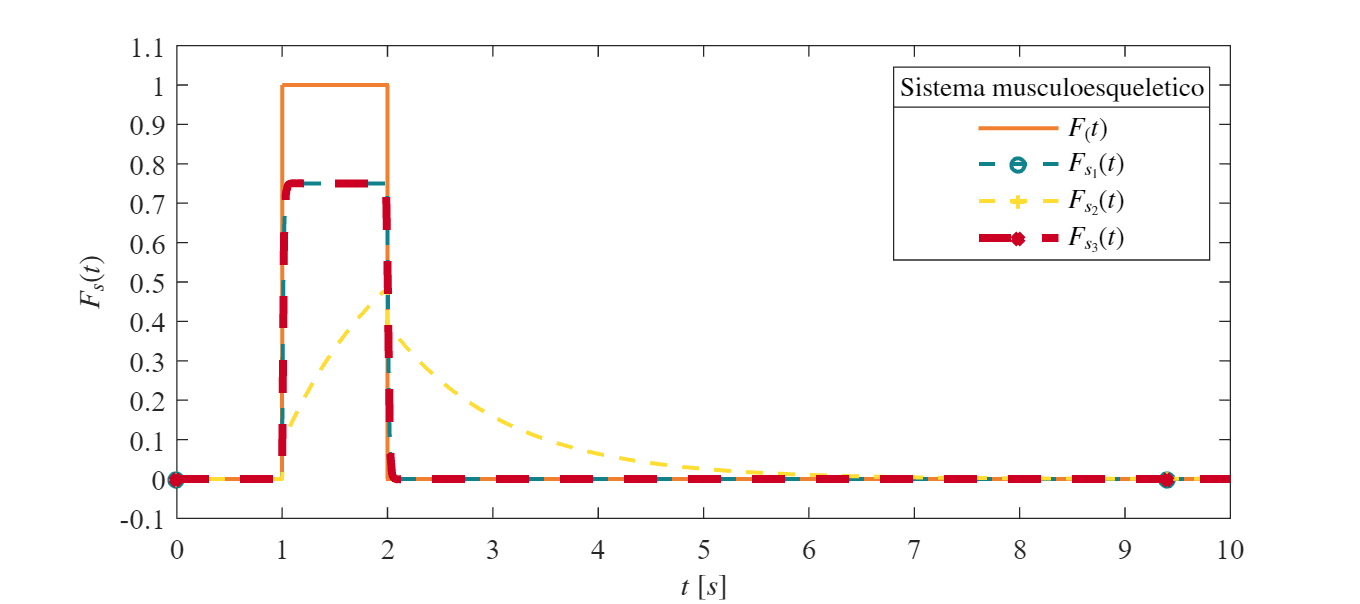

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistemaC';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
x = sim(file,parameters);
plotsignals(x.t,x.F,x.Fs1,x.Fs2,x.Fs3)

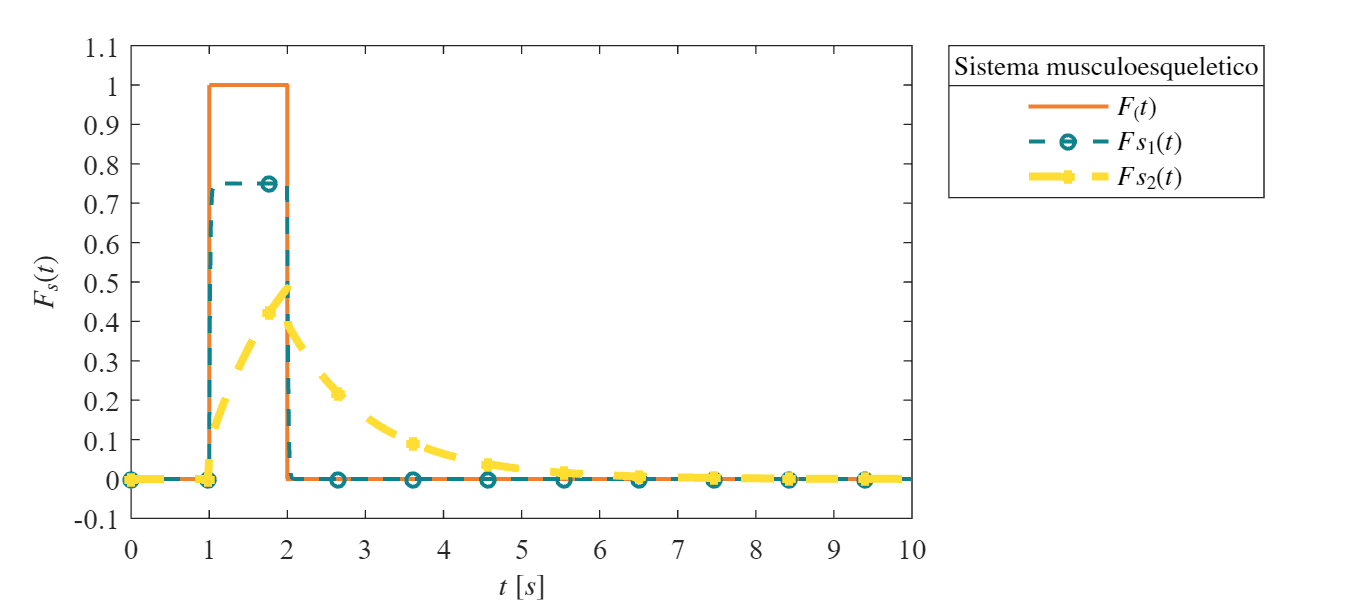

x2 = sim(file,parameters);
plotsignals2(x2.t,x2.F,x2.Fs1,x2.Fs2)

## Respuesta en lazo abierto

## Respuesta al impulso

## Respuesta a la rampa

## Respuesta a la función sinusoidal

## Función: Respuesta a las señales

function plotsignals(t,F,Fs1,Fs2,Fs3)
set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;

mycolors = [240,128,48;
15,130,140;
255,221,51;
204,0,34;
143,163,30;
107,36,12;]/255;
colororder(mycolors)



p = plot(t,F,'-',t,Fs1,'--o',t,Fs2,'--+',t,Fs3,'--x',...
   'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:10000:length(t));
set(p(4), 'LineWidth',3)
L = legend('$F_(t)$','$F_{s_1}(t)$','$F_{s_2}(t)$','$F_{s_3}(t)$','$PID(t)$');
set(L,'Interpreter','Latex','FontSize',10);
title(L,'Sistema musculoesqueletico','FontSize',10)

 xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
 ylabel('$F_s(t)$','Interpreter','Latex','FontSize',11)

xlim([0,10]);xticks(0:1:10);
ylim([-0.1,1.1]);yticks(-0.1:0.1:1.1);


exportgraphics(gcf,['Sistema_musculoesqueletico ','.pdf'],'ContentType','vector')
exportgraphics(gcf,['Sistema_musculoesqueletico','.png'],'ContentType','vector')
end

function plotsignals2(t,F,Fs1,Fs2)
set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [240,128,48;
15,130,140;
255,221,51;
204,0,34;
143,163,30;
107,36,12;]/255;
colororder(mycolors)

p = plot(t,F,'-',t,Fs1,'--o',t,Fs2,'--+',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
set(p(3),'LineWidth',3);
 L = legend('$F_(t)$','$F{s_1}(t)$','$F{s_2}(t)$');
 set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');

title(L,'Sistema musculoesqueletico','FontSize',10)

 xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
 ylabel('$F_s(t)$','Interpreter','Latex','FontSize',11)

xlim([0,10]);xticks(0:1:10);
ylim([-0.1,1.1]);yticks(-0.1:0.1:1.1);

 exportgraphics(gcf,['Sistema_musculoesqueletico_2','.pdf'],'ContentType','vector')
exportgraphics(gcf,['Sistema_musculoesqueletico_2','.png'],'ContentType','vector')

end
